clear all;

T1 = 0.6;
T2_ = 0.9;

T = T1 / 2

T = 0.3000

T2 = T2_ * 1.2

T2 = 1.0800


d1 = exp(-T / T1)

d1 = 0.6065

%d2 = exp(-T / T2)
d2 = exp(-T / T2_)

d2 = 0.7165

a1 = -d1 -d2

a1 = -1.3231

a0 = d1 * d2

a0 = 0.4346


q0 = 10

q0 = 10



%======================================================
% GRAPHICS
%======================================================

set_param('schem_1/y', 'VariableName', 'y');
set_param('schem_1/u', 'VariableName', 'u');
set_param('schem_1/g', 'VariableName', 'g');
set_param('schem_1/f', 'VariableName', 'f');



out = sim('schem_1');
y_ = out.y.Data;
t_ = out.y.Time;
u_ = out.u.Data;
tu_ = out.u.Time;
g_ = out.g.Data;
tg_ = out.g.Time;
f_ = out.f.Data;
tf_ = out.f.Time;

T = T1 / 2

T = 0.3000

T2 = T2_ * 0.8

T2 = 0.7200

d1 = exp(-T / T1)

d1 = 0.6065

%d2 = exp(-T / T2)
a1 = -d1 -d2

a1 = -1.3231

a0 = d1 * d2

a0 = 0.4346

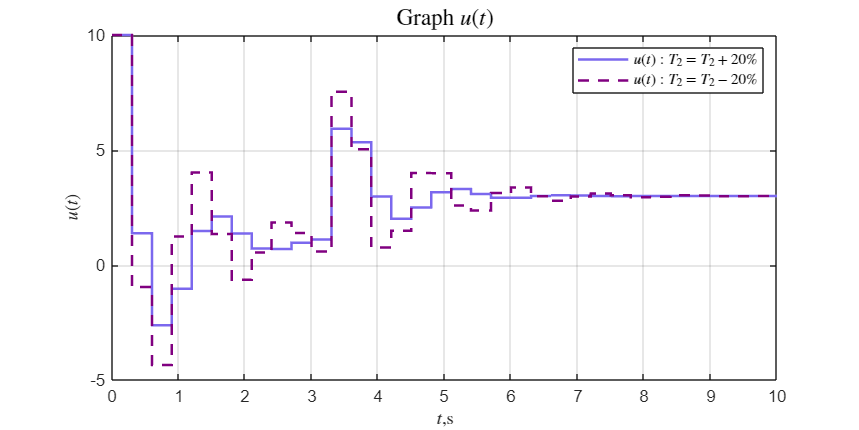


out = sim('schem_1');
y_1 = out.y.Data;
t_1 = out.y.Time;
u_1 = out.u.Data;
tu_1 = out.u.Time;
f_1 = out.f.Data;
tf_1 = out.f.Time;


% Построение графика

% Определяем цвета для линий
a_color = '#00FFFF'; 
b_color = '#7B68EE';
c_color = '#800080'; 
d_color = '#0000CD';
e_color = '#EE82EE';

figure('Position', [100 100 800 400]);
stairs(tu_, u_, '-', 'LineWidth', 1.5, 'Color', b_color);
hold on;
stairs(tu_1, u_1, '--', 'LineWidth', 1.5, 'Color', c_color);

grid on;

title('Graph $u(t)$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$u(t)$','Interpreter', 'latex' );
xlabel('$t$,s', 'Interpreter', 'latex');
legend('$u(t): T_2 = T_2 + 20 \%$','$u(t): T_2 = T_2 - 20 \%$','Interpreter', 'latex')
xlim([0, 10])
hold off;

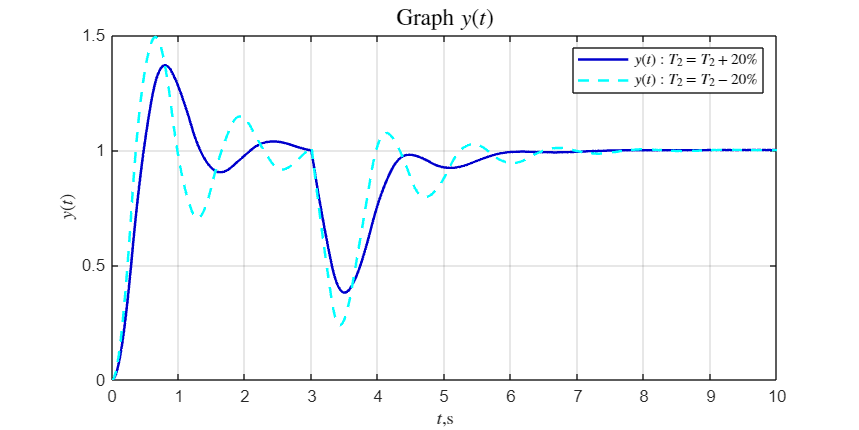


full_path = ['C:\Users\user\Desktop\STUDY_2.0\4 курс робототехника\ДискрСистУпр\DiscreteSystems\lab_3\Discrete_report_3\pic\' ...
    '5_2_u.png'];

%exportgraphics(gcf, full_path, 'Resolution', 300);


figure('Position', [100 100 800 400]);
plot(t_, y_, '-', 'LineWidth', 1.5, 'Color', d_color);
hold on;
plot(t_1, y_1, '--', 'LineWidth', 1.5, 'Color', a_color);

grid on;

title('Graph $y(t)$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$y(t)$','Interpreter', 'latex' );
xlabel('$t$,s', 'Interpreter', 'latex');
legend('$y (t): T_2 = T_2 + 20 \%$','$y (t): T_2 = T_2 - 20 \%$','Interpreter', 'latex')
xlim([0, 10])
hold off;

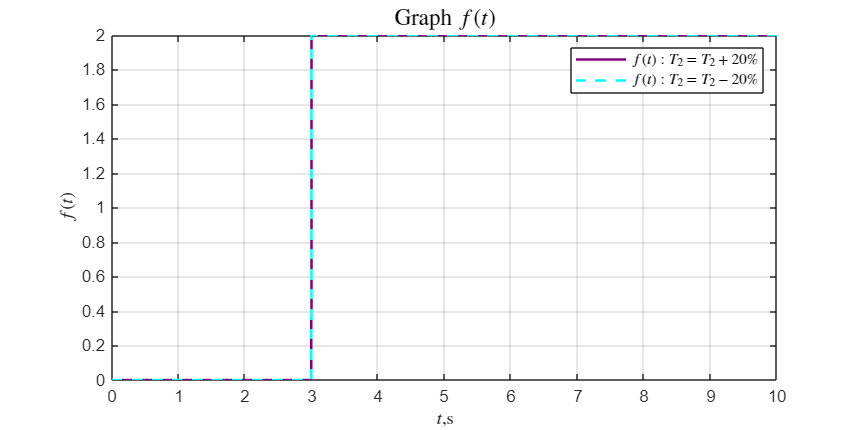


full_path = ['C:\Users\user\Desktop\STUDY_2.0\4 курс робототехника\ДискрСистУпр\DiscreteSystems\lab_3\Discrete_report_3\pic\' ...
    '5_2_y.png'];

%exportgraphics(gcf, full_path, 'Resolution', 300);


figure('Position', [100 100 800 400]);
plot(tf_, f_, '-', 'LineWidth', 1.5, 'Color', c_color);
hold on;
plot(tf_1, f_1, '--', 'LineWidth', 1.5, 'Color', a_color);

grid on;

title('Graph $f(t)$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$f(t)$','Interpreter', 'latex' );
xlabel('$t$,s', 'Interpreter', 'latex');
legend('$f (t): T_2 = T_2 + 20 \%$','$f (t): T_2 = T_2 - 20 \%$','Interpreter', 'latex')
xlim([0, 10])
hold off;


full_path = ['C:\Users\user\Desktop\STUDY_2.0\4 курс робототехника\ДискрСистУпр\DiscreteSystems\lab_3\Discrete_report_3\pic\' ...
    '5_2_f.png'];

%exportgraphics(gcf, full_path, 'Resolution', 300);

%{
figure('Position', [100 100 800 400]);
plot(tg_, g_, '-', 'LineWidth', 1.5, 'Color', c_color);

grid on;

title('Graph $g(t)$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$g(t)$','Interpreter', 'latex' );
xlabel('$t$,s', 'Interpreter', 'latex');
legend('$g (t)$','Interpreter', 'latex')
xlim([0, 10])
hold off;

full_path = ['C:\Users\user\Desktop\STUDY_2.0\4 курс робототехника\ДискрСистУпр\DiscreteSystems\lab_3\Discrete_report_3\pic\' ...
    '3_1_g.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);
%}

